### Istogramma

L'istogramma è un vetore che conta quante volte compare ogni liveli di grigio (da 0 a 255) in un'immagine.

È possibile usare la funzione **imhist** per calcolare e visualizzare facilmente l'istogramma di un'immagine in scala di grigi

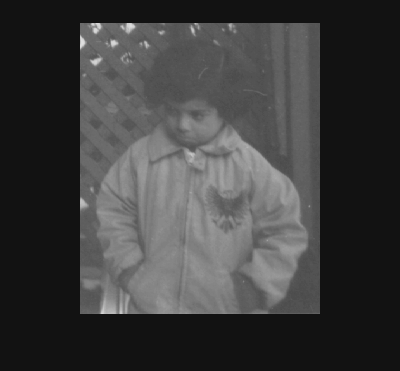

img_gray = imread("pout.tif");
figure;imshow(img_gray);

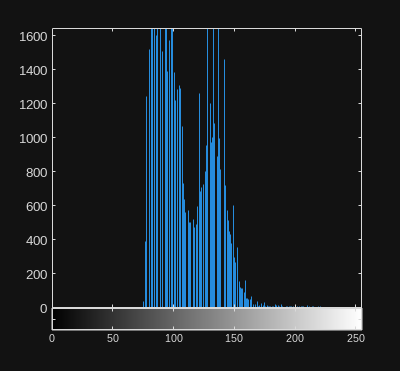

imhist(img_gray);

### Istogramma di un'Immagine a Colori

Per un'immagine RGB, calcoliamo tre istogrammi separati, uno per ogni canale.

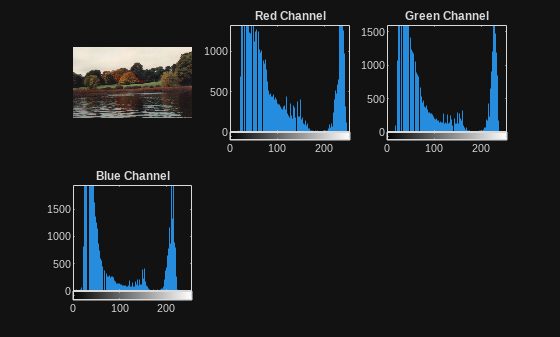

img_color = imread("autumn.tif");

R = img_color(:,:,1);
G = img_color(:,:,2);
B = img_color(:,:,3);

figure; subplot(2,3,1); imshow(img_color);
subplot(2,3,2); imhist(R); title('Red Channel');
subplot(2,3,3); imhist(G); title('Green Channel');
subplot(2,3,4); imhist(B); title('Blue Channel');

### Funzione Personalizzata per Visualizzare l'Istogramma

La Somma Cumulativa c(i) di un istogramma h è la somma di tutti i conteggi di h fino all'intensità i.

function hplot = plothist(img)
    % Calcolo l'istogramma come vettore riga
    h = imhist(uint8(img),256);

    % Creo Immagine di output
    hplot = ones(120,256,3,"uint8") * 255;
    
    % Somma Cumulativa
    c = 101 - ceil(100 * cumsum(h) / sum(h));

    % Normalizzazione
    m = 101 - ceil(100*double(h)/double(max(h(:))));

    for i = 1 : 256
        hplot(m(i):100,i,:) = 0; % barretta nera dell'istogramma
        hplot(c(i),i,:) = [255,0,0]; % pixel rosso per somma comulativa
        hplot(102:120,i,:) = i-1; % barretta alta 19 per ogni colore di grigio
    end
end

plothist(img_gray);

### Operazioni sugli istogrammi

### **1 - Stretching del Contrasto**

Lo stretching è un'operazione lineare che rimappa i livelli di grigio per sfruttare 'intero range di colori. Si prende il minimo presente nell'immagine (min_g) e lo si mappa a 0. Si prende il massimo (max_g) e lo si mappa a 255. Tutti i valori intermedi vengono scalati linearmente. Questo aumenta il contrasto ma crea dei "buchi" nell'istogramma poiché non crea nuovi livelli di grigio.

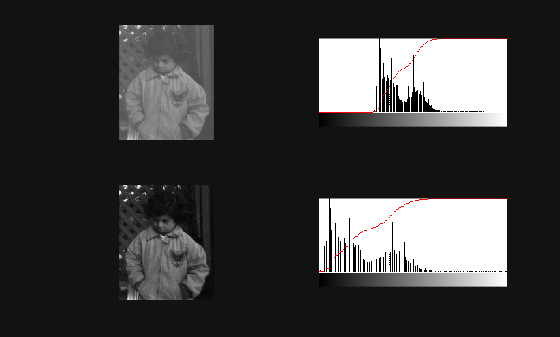

function out = mystretch(img)
    min_g = double(min(img(:)));
    max_g = double(max(img(:)));
    out = uint8(255 * (double(img) - min_g)/(max_g-min_g));
end

function out = mystretch_v2(img)
    min_g = double(min(img(:)));
    max_g = double(max(img(:)));
    lut = uint8(255 * ((0:255) - min_g)/(max_g-min_g));
    out = lut(img+1);
end

img_stretched = mystretch_v2(img_gray);
figure; 
subplot(2,2,1); imshow(img_gray);
subplot(2,2,2); imshow(plothist(img_gray));
subplot(2,2,3); imshow(img_stretched);
subplot(2,2,4); imshow(plothist(img_stretched));

### 2 - Equalizzazione dell'istogramma

L'equalizzazione è una tecnica non-lineare che mira a produrre un'immagine con un istogramma il più possibile piatto. Questo si ottiene ridistribuendo i valori di grigio in modo che ogni livello di intensità sia presente con una frequenza simile.

La funzione di trasmissione che permette di fare ciò è la **Somma Cumulativa CDF** dell'istogramma. 

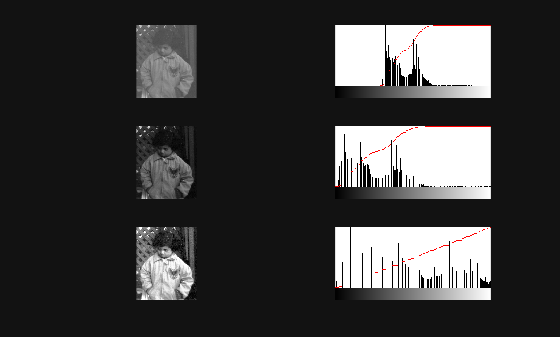

function out =myequalization(img)
    s = numel(img) / 256; % livello di soglia
    h = imhist(uint8(img),256); % istogramma dell'immagine
    cdf = cumsum(h); % calcola la sommma cumulativa
    lut = uint8(round(cdf / s)); % Crea una LUT normalizzando la CDF
    out = lut(img+1); % applica la LUT
    
end

img_eq = myequalization(img_gray);
figure; 
subplot(3,2,1); imshow(img_gray);
subplot(3,2,2); imshow(plothist(img_gray));
subplot(3,2,3); imshow(img_stretched);
subplot(3,2,4); imshow(plothist(img_stretched));
subplot(3,2,5); imshow(img_eq);
subplot(3,2,6); imshow(plothist(img_eq));

### 3 - Edge Histogram

A differenza di un istogramma standard che analizza la luminosità. un **edge Histogram** analizza la **distribuzione degli angoli dei contorn**i in un'immagine. E uno strumento potente per la descrizione di forme e confronto di immagni; infatti due immagini sono uguali non se presentnao lo stesso numero di pixel di un certo colore (istogrammi uguali) ma piuttosto potrebbero essere la stessa immagine se sono presenti gli stessi angoli in grado e in numero.

- Asse X rappresenta l'angolo del bordo, tipicamente da 0 a 359, che per eficienza potrebbero essere ridotti a 0-35.

- Asse y rappresenta il numero di pixel di contorno che hanno quel determinato angolo

- Permette di identificare le direzioni dominanti in un'immagine (es. un'immagine con molti edifici avrà picchi a 0, 90, 180 270 gradi.

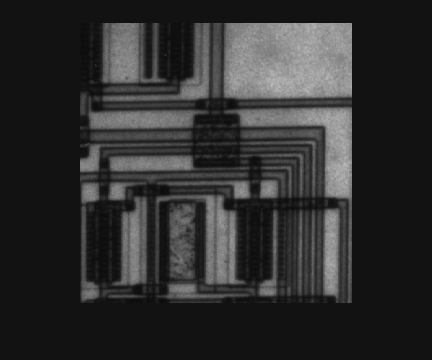

function edge_histogram(img)

    % Prepariamo l'immagine
    if size(img,3) == 3
        imgray = rgb2gray(img);
    end

    % Rileva i bordi con Sobel
    [~,~,Gx,Gy] = edge(img,"sobel");
    [magnitude, angles] = imgradient(Gx,Gy);

    % Normalizza gli angoli da [-180,180] a [0,360]
    angles = mod(round(angles + 180),360);


    % Calcola l'istogramma degli angoli, considerando solo brodi forti
    magnitudeThreshold = max(magnitude(:)) * 0.2; % Soglia empirica
    edgePixelsAngles = angles(magnitude > magnitudeThreshold);
    edgeHist = histcounts(edgePixelsAngles, 0:360);

    % Crea l'immagine dell'istogramma per la visualizzazione
    hplot = uint8(ones(120,360,"uint8") * 255);

    % normalizza l'altezza
    edgeHistNorm = edgeHist / max(edgeHist);

    for i = 1 : 360
        barHeight = ceil(edgeHistNorm(i)* 100);
        if barHeight > 0
            hplot((100 - barHeight + 1):100, i) = 0; % Barra nera
        end
        hplot(100 + 1:end, i) = uint8((i - 1) * (255 / 360)); % Barretta colore
    end

     % Visualizza l'istogramma degli angoli
    figure;
    imshow(hplot);
    title('Edge Histogram');
end


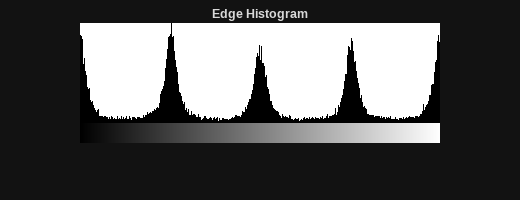

img_test = imread('circuit.tif');

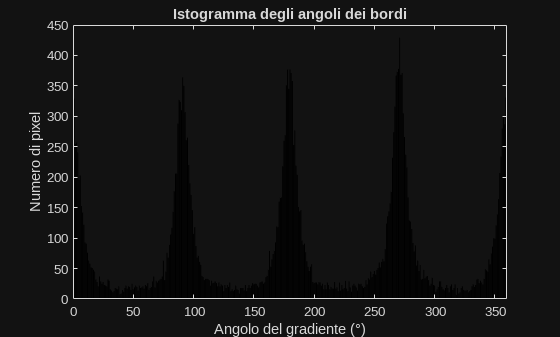

figure;imshow(img_test);
edge_histogram(img_test);
% Versione più semplice
function edge_angle_histogram(img)
    % Converti in scala di grigi se necessario
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    % Calcola modulo e direzione del gradiente
    [mag, dir] = imgradient(img);

    % Normalizza gli angoli in [0, 360)
    angles = mod(round(dir + 180), 360);

    % Considera solo bordi forti
    threshold = max(mag(:)) * 0.2;
    selected_angles = angles(mag > threshold);

    % Calcola l'istogramma
    edgeHist = histcounts(selected_angles, 0:360);

    % Mostra istogramma come grafico
    figure;
    bar(0:359, edgeHist, 'k');
    xlabel('Angolo del gradiente (°)');
    ylabel('Numero di pixel');
    title('Istogramma degli angoli dei bordi');
    xlim([0 360]);
end


figure; edge_angle_histogram(img_test);

## Thresholding (sogliatura)

La sogliatura è il processo di convertire un'immagine in scala di grigi in un'immagine binaria. Ogni pixel viene classificato come "foreground" (bianco) o background(nero) in base a un valore di soglia t.

### Threshold Globale

Si usa un solo valore di **t **per tutta l'immagine. Funziona bene se l'istogramma è **bimodale** (ha due picchi netti).

#### Thresholf Geometrico

Il metodo più semplice per trovare il livello di soglia in un'immagine bimodale è col threashold geometrico, che in questo caso è circa 85.

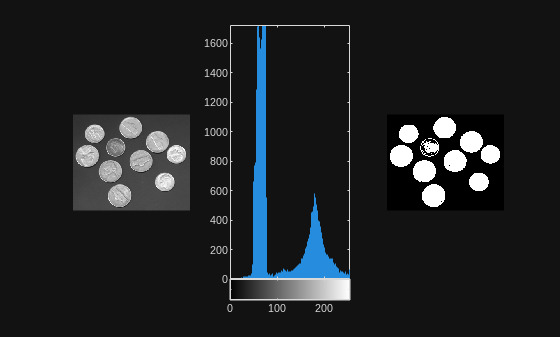

img_coin = imread("imgs/coins.png");
figure; subplot(1,3,1);imshow(img_coin);
subplot(1,3,2); imhist(img_coin);

img_trh1 = img_coin > 120;
subplot(1,3,3); imshow(img_trh1);

#### Thresholdi con Media o Mediana

Se l'istogramma non è bimodale, un aprocco semplice ma inefficiente è usare la media o la mediana dei vaori di grigio come soglia. Fornisce scarsi risultati.

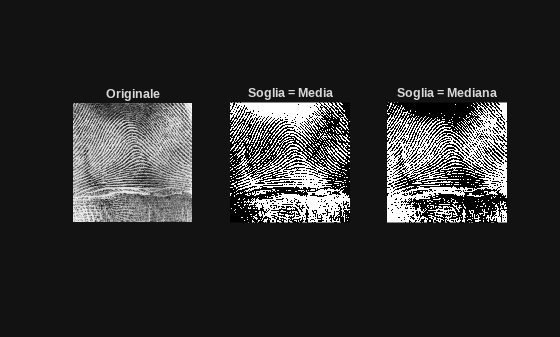

img_finger = imread("imgs/fingerprint.png");
figure('Name', 'Thresholding Semplice');
subplot(1, 3, 1); imshow(img_finger); title('Originale');
m = mean(img_finger(:));
subplot(1, 3, 2); imshow(img_finger > m); title('Soglia = Media');

md = median(img_finger(:));
subplot(1, 3, 3); imshow(img_finger > md); title('Soglia = Mediana');

#### Threashold Iterativo (OTSU)

Questo algoritmo trova una soglia stabile in modo iterativo, calcolando iteratvamente la media dei due gruppi. Funziona su istogrammi bimodali.

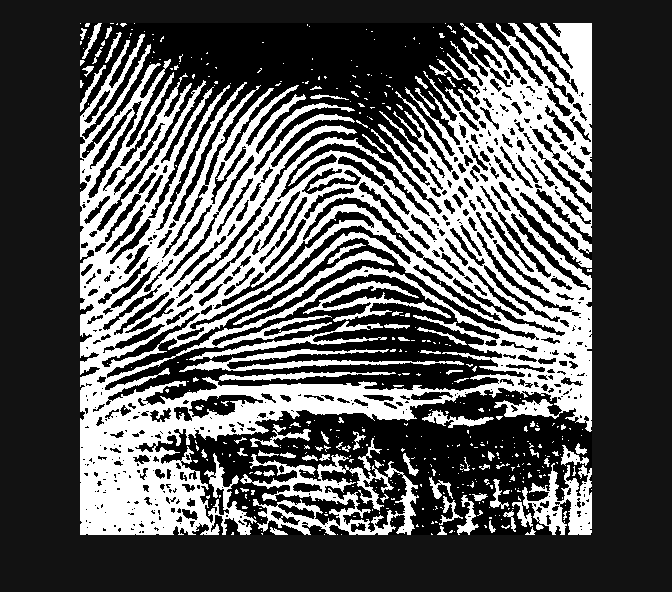

function binaryImage = OtsuThreshold(image)

   % Inizializza la soglia ad un valore casuale
   T_prev = mean(image(:));
   deltaT = 1; % Soglia di convergenza

   while true
        % Calcola due gruppi
        g1 = image(image <= T_prev);
        g2 = image(image > T_prev);

        % Calcola nuova soglia
        T_new = (mean(g1) + mean(g2))/2;

        % Verifica la convergenza
        if abs(T_new - T_prev) < deltaT
            break;
        end
        T_prev = T_new;
   end

   % Applica la soglia
   binaryImage = image > T_new;
end


soglia_iterativa = OtsuThreshold(img_finger);
figure; imshow(soglia_iterativa);

#### Threshold Adattivo (Locale)

L'idea è semplice: invece di una soglia unica per tutta l'immagine, se ne calcola una diversa per ogni pixel basandosi sulla **media dei pixel in una piccola finestra attorno ad esso**. Questo metodo si adatta a variazioni di luce locali.

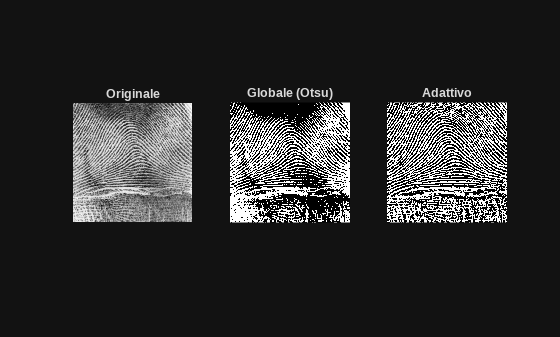

function binaryImage = adaptiveThreshold(image,blockSize)
    
    image = im2double(image);
    binaryImage = zeros(size(image));
    halfBlock = floor(blockSize / 2);
    [rows, cols] = size(image);

    for i = 1:rows 
        for j = 1:cols 
            % Estrai finestra locale
            rMin = max(i - halfBlock,1);
            rMax = min(i + halfBlock, rows);
            cMin = max(j - halfBlock,1);
            cMax = min(j + halfBlock, cols);

            local_block = image(rMin:rMax,cMin:cMax);
            localThreashold = mean(local_block(:));
            binaryImage(i,j) = image(i,j) > localThreashold;
        end
    end

   binaryImage = logical(binaryImage); % per sicurezza

end

img_adaptive = adaptiveThreshold(img_finger, 35);

% Confronto con threshold globale (Otsu)
img_global = imbinarize(img_finger);

% Visualizza
figure;
subplot(1, 3, 1); imshow(img_finger); title('Originale');

subplot(1, 3, 2); imshow(img_global); title('Globale (Otsu)');
subplot(1, 3, 3); imshow(img_adaptive); title('Adattivo');